    % Helper Functions
function a = get_a(t,amax,t_ahold,t_vhold)
    t_vhold = 0;
    a = zeros(size(t));
    
    idx1 = (0 <= t) & (t < t_ahold);
    idx2 = ((t_ahold <= t) & (t < (t_ahold + t_vhold)));
    idx3 = (((t_ahold + t_vhold) <= t) & (t < (2*t_ahold + t_vhold)));
    
    a(idx1) = amax;
    a(idx2) = 0;
    a(idx3) = -amax;
end

function [a,v,s] = get_kin_functions(dt,t,amax,t_ahold,delta_s)
    t_vhold = 0;
    
    a = get_a(t,amax,t_ahold,t_vhold) * sign(delta_s);
    v = cumsum(a) * dt;
    s = cumsum(v) * dt;
end

function t_ahold = get_t_ahold_without_t_vhold(delta_s,amax)
    t_ahold = sqrt(abs(delta_s) / amax);
end

function center_zero_dual_axis(y1, y2)
    padding = .2;
    padding_factor = 1 + padding;

    yyaxis left
    m1 = max(abs(y1)) * padding_factor;
    ylim([-m1 m1])
    
    yyaxis right
    m2 = max(abs(y2)) * padding_factor;
ylim([-m2 m2])
end

close all; clear;

dt = 0.001; % Time Resolution = 1ms
t = [];

dim = 4;    % Specify dimensions

% Initialize Vectors
a = zeros([dim 0]);
v = zeros([dim 0]);
s = zeros([dim 0]);

a_peak = zeros([1 dim]);

a_mot = 1

a_mot = 1


m_x = 5.7

m_x = 5.7000

m_y = 1

m_y = 1

m_z = .5

m_z = 0.5000


% amax = [f_mot/m_x f_mot/m_y f_mot/m_z 1000];
amax = [a_mot a_mot a_mot 10000];

dist_to_belt = .45 % 450cm

dist_to_belt = 0.4500

depth_to_pickup = 0.05

depth_to_pickup = 0.0500

height_over_belt = .1 % 100cm

height_over_belt = 0.1000

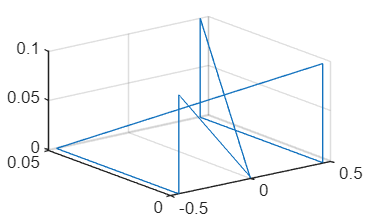


positions = [
    [0,                         0,                                 0,    0],
    [-dist_to_belt,             0,                  height_over_belt,    0],
    [-dist_to_belt,             0,                                 0,    0],
    [-dist_to_belt,            depth_to_pickup,                    0,    0],
    [ dist_to_belt,             0,                  height_over_belt,   pi],
    [ dist_to_belt,             0,                                 0,   pi],
    [ dist_to_belt,             depth_to_pickup,                   0,   pi],
    [ dist_to_belt,             depth_to_pickup,    height_over_belt,   pi],
    [0,                         0,                                 0,    0],
    ];

positions_size = size(positions);
num_of_positions = positions_size(1);

for i = [1:num_of_positions - 1]
    position = positions(i,:);
    next_position = positions(i + 1,:);

    delta_position = next_position - position;

    longest_time_i = 1;
    longest_time = 0;
    longest_t_ahold = 0;
    % Find longest time taken
    for j = 1:dim
        t_ahold = get_t_ahold_without_t_vhold(delta_position(j), amax(j));
        t_tot = 2 * t_ahold;
        if t_tot > longest_time
            longest_time_i = j;
            longest_time = t_tot;
            longest_t_ahold = t_ahold;
        end
    end

    for i = 1:dim
        a_peak(i) = abs(delta_position(i)) / (longest_t_ahold^2);
    end

    t_temp = 0:dt:longest_time;

    for i = 1:dim
        [a_temp,v_temp,s_temp] = get_kin_functions(dt,t_temp,a_peak(i),longest_t_ahold, delta_position(i));

        a(i, length(t) + 1: length(t) + length(a_temp)) = a_temp;
        v(i, length(t) + 1: length(t) + length(v_temp)) = v_temp;

        if ~isempty(t)
            s(i, length(t) + 1: length(t) + length(s_temp)) = s_temp + s(i, length(t));
        else
            s(i, length(t) + 1: length(t) + length(s_temp)) = s_temp;
        end
    end

    if ~isempty(t)
        t(end + 1: end + length(t_temp)) = t_temp + t(end);
    else
        t(end + 1: end + length(t_temp)) = t_temp;
    end
end


% Generate Plots
if dim == 2
    plot(s(1,:),s(2,:))
elseif dim == 3 | dim == 4
    plot3(s(1,:),s(2,:),s(3,:))
end
grid on;

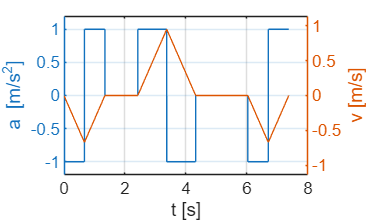

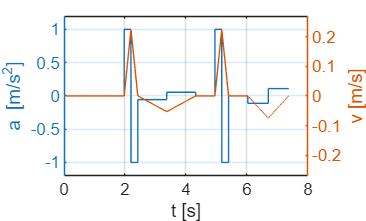

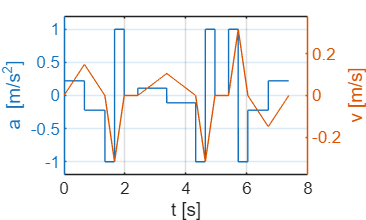

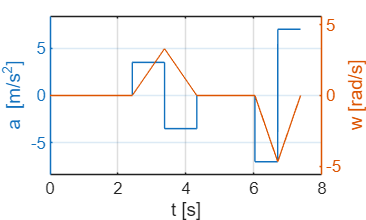


for i = 1:dim
    figure();
    yyaxis left;
    plot(t,a(i,:));
    ylabel("a [m/s^2]");
    yyaxis right;
    plot(t,v(i,:));

    if i ~= 4
        ylabel("v [m/s]");
    else
        ylabel("w [rad/s]");
    end

    grid on;

    xlabel("t [s]");

    center_zero_dual_axis(a(i,:),v(i,:));
end